# Matrices especiales

Hay un grupo de matrices que destacan por encima de cualquier matriz `nxm`. A continuación se muestra se las detalla y al final se muestra una tabla de resumen con las funciones que las generan.

## Matriz vacía

Se inicia la descripción de matrices especiales con la matriz vacía. En esencia no hay ninguna función que cree una matriz vacía, debido a que es suficiente con abrir y cerrar corchetes `[]` para generarla.

clear
A = []


A =

     []



v01 = randi(10, 1, 10)

v01 =      2    10    10     5     9     2     5    10     8    10



v01 =

  1×0 empty double row vector



## Matriz de ceros

Una matriz de ceros se caracateriza, como su nombre lo indica, por una matriz en la que todos sus elementos con `0`. Mediante la función `zeros` es posible generarla.

clear
M0 = zeros(3, 2)

M0 =      0     0
     0     0
     0     0


Un ejemplo podría ser crear un vector fila con el valor de `pi` en todas las entradas.

Mpi = zeros(3) + pi

Mpi =     3.1416    3.1416    3.1416
    3.1416    3.1416    3.1416
    3.1416    3.1416    3.1416


## Matriz de unos

Esta matriz es similar a la matriz de ceros: en lugar de tener `0` en sus elementos tiene `1`. Con la función `ones` es posible generarla.

clear
M1 = ones(3, 2)

M1 =      1     1
     1     1
     1     1


Un ejemplo podría ser crear un vector fila con el valor de `e` en todas las entradas.

Mpi = ones(3) * pi

Mpi =     3.1416    3.1416    3.1416
    3.1416    3.1416    3.1416
    3.1416    3.1416    3.1416


**Nota:** A simple vista pareciera no tener utilidad una matriz de ceros o unos, sin embargo, se las puede utilizar como un marcador de posición (**placeholder**) para futuros cálculos, por dar un ejemplo.

- Las matrices de marcadores (**placeholders**) son de gran utilidad en estructuras de bucle (**loop**) que se estudiarán en capítulos posteriores.

## Matriz diagonal

La función `diag` extrae la diagonal principal de una matriz.

clear
M = randi(10, 3)

M =     10     2     3
     6     3     9
     2     9     3


Vdiag = diag(M)

Vdiag =     10
     3
     3


Mdiag = diag(Vdiag)

Mdiag =     10     0     0
     0     3     0
     0     0     3


Añadiendo un segundo argumento **k** a la función `diag` es posible extraer otras diagonales. La siguiente figura detalla cómo funciona.

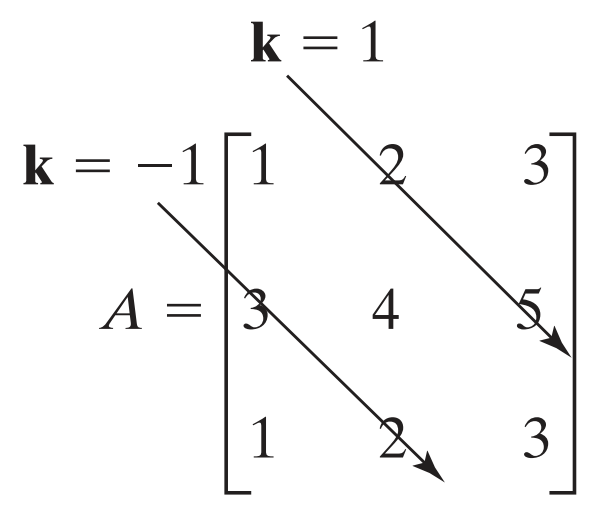

% Su código va aquí :)

Sin embargo, ¿qué pasaría si en lugar de pasarle una matriz como argumento a la función `diag` le pasamos un vector?

% Su código va aquí :)

Como se observa en los resultados, pasarle como argumento un vector fila/columna a la función `diag` generará una matriz en la que la diagonal principal serán los valores del vector y el resto de entradas serán cero.

Por otra parte, ¿qué pasaría si le pasamos un vector y un valor para **k**?

% Su código va aquí :)

Como podemos observar, si le pasamos un valor de **k** a la función `diag`, habiéndole pasado un vector como primer argumento, generará una matriz en la que la diagonal donde se ubiquen los valores del vector dependerá del valor de **k**.

## Matriz mágica

MATLAB incluye una función matricial llamada `magic` que genera una matriz con propiedades inusuales.

- La suma de las filas es la misma.

- La suma de las columnas es la misma.

- La suma de las diagonales es la misma.

- La suma de las filas, columnas y diagonales es la misma.

Sin embargo, actualmente parece no existir algún uso práctico para las matrices mágicas, excepto que son divertidas.

Mmagic = magic(4)

Mmagic =     16     2     3    13
     5    11    10     8
     9     7     6    12
     4    14    15     1


Revisemos la suma de las columnas:

sum(Mmagic)

ans =     34    34    34    34


Revisemos la suma de las filas:

sum(Mmagic, 2)

ans =     34
    34
    34
    34


Revisemos la suma de la diagonal principal:

sum(diag(Mmagic))

ans = 34

Para revisar la suma de la otra diagonal es necesario "voltear" la matriz. Para ello utilizamos la función `fliplr` (se detalla esta función en la tabla resumen del final).

sum(diag(fliplr(Mmagic)))

ans = 34

Tal como esperábamos, se cumplen las propiedades de una matriz mágica.